# Laboratori 8 - Victor Correal

## A.Codi base

### Visualització imatge base

Obrir imatge i comprovar que és una imatge RGB:

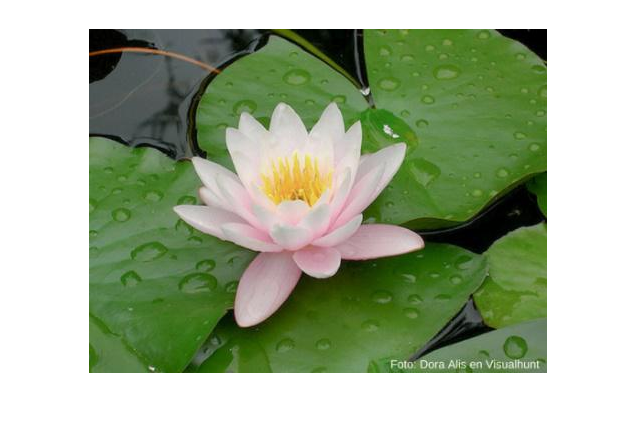

I = imread("fotoPlanta.jpg");
imshow(I)

sizeI = size(I);
MAXFILA = sizeI(2);
MAXCOL = sizeI(1);

Tenim una imatge de 344x458 pixels per cada canal RGB.

### Rectangle del usuari

Obtenir del usuari el rectangle que emmarca l’objecte. Utilitzeu *rect = getrect. *Vigileu que *rect *té el format x y amplada alçada (en lloc de fila i columna).

%rect = getrect
rect = [75, 49, 271, 267];

Mirem el que ha sel·lecionat l'usuari, obtenim la imatge HSV:

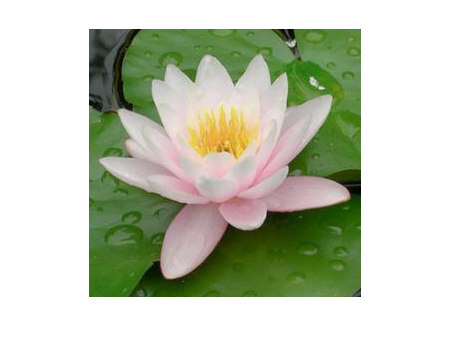

x1 =rect(1);
x2 = x1 + rect(3);
y1 =rect(2);
y2 = y1 + rect(4);
imSel = I(y1:y2, x1:x2,:);
imshow(imSel);

### Kmeans

Obtenir la imatge **HSV**: r*gb2hsv.*	

imHSV = rgb2hsv(I);
Hx = arrayfun(@(x) cos(x), imHSV(:,:,1));
Hy = arrayfun(@(y) sin(y), imHSV(:,:,1));
imHxHySV = imHSV(:,:,2:3);
imHxHySV(:,:,3) = Hx; %agafem el sinus, cosinus per evitar
imHxHySV(:,:,4) = Hy; %el factor ciclic del Hue.

Preparem la taula pel *kmeans*. Cal construir una taula **O **amb tantes files com píxels i les següents columnes:

[MAXFILA, MAXCOL, chan] = size(imHxHySV);
O = reshape(imHxHySV, MAXFILA*MAXCOL,4);

Agrupem els colors en **k**	classes amb kmeans i obtenim la classificació **C**, per exemple k = 20. 

k = 20 %nombre de classes

k = 20

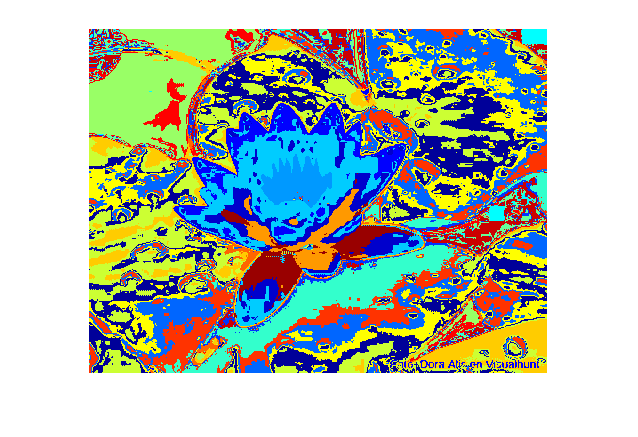

C = kmeans(O,k);
%Visualització de la imatge:
IC = reshape(C,MAXFILA,MAXCOL); 
rgb = label2rgb(IC); 
imshow(rgb)

### Mask

Construïm una imatge de valors booleans anomenada **MASK **de la mateixa mida que **I **amb els valors a zero si està fora del rectangle i 1 si està dins (fig 5).

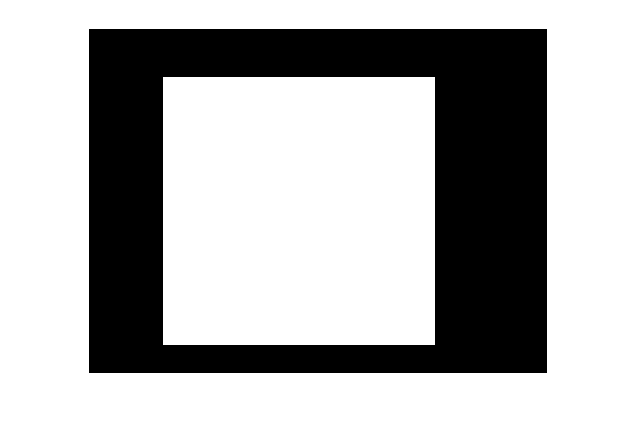

MASK = zeros(sizeI); %0 fora del rectangle
MASK = MASK(:,:,1);
MASK(y1:y2, x1:x2) = 1; %1 dins del rectangle
imshow(MASK);	

Ara construïm un vector **H **que indicarà si un representant de color o classe cau dins del rectangle o no. Tal que H = [C, MASK(:)];

A continuació, comptem per a cada representant de color quants píxels han caigut a fora i quants a dins. Guardem els resultats en dos arrays **Hist0 **i **Hist1**. Evidentment, la mida de Hist0 i Hist1 ha de ser  igual al nombre de classes k. 	

H = [C, MASK(:)];
aux = size(H);
Hist0 = zeros(k,1);
Hist1 = zeros(k,1);
for x = 1:aux(1)
    claseActual = H(x,1);  
    dinsForaActual = H(x,2);
    if dinsForaActual == 0
        Hist0(claseActual) = Hist0(claseActual) + 1;
    else
        Hist1(claseActual) = Hist1(claseActual) + 1;
    end
end

Llavors decidim si un representant de color pertany a la figura que es vol segmentar comparant les seves aparicions dins i fora del rectangle. Guardem la decisió en un vector anomenat ***RES***. Quelcom com RES = Hist1 > Hist0;

RES = Hist1 > Hist0;

Casi per últim, decidim per a cada  píxel de la matriu H si forma part de la figura o no utilitzant la informació que conté RES. Guardem el resultat en un vector **M **i el mostrem per pantalla.

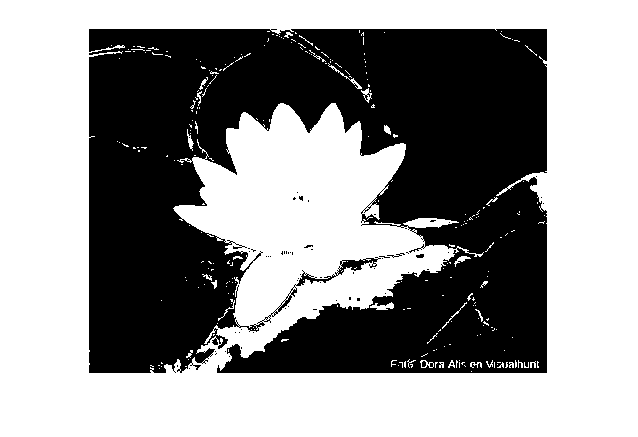

H = [C, MASK(:)];
aux = size(H);
M = zeros((aux:1));
for x = 1:aux(1)
    claseActual = H(x,1);
    dinsForaActual = H(x,2);
    M(x) = RES(claseActual);  
end
M = reshape(M, MAXFILA,MAXCOL); 
imshow(M);

I per últim filtrem la imatge per a que el resultat no sigui tant sorollós i més compacte.  

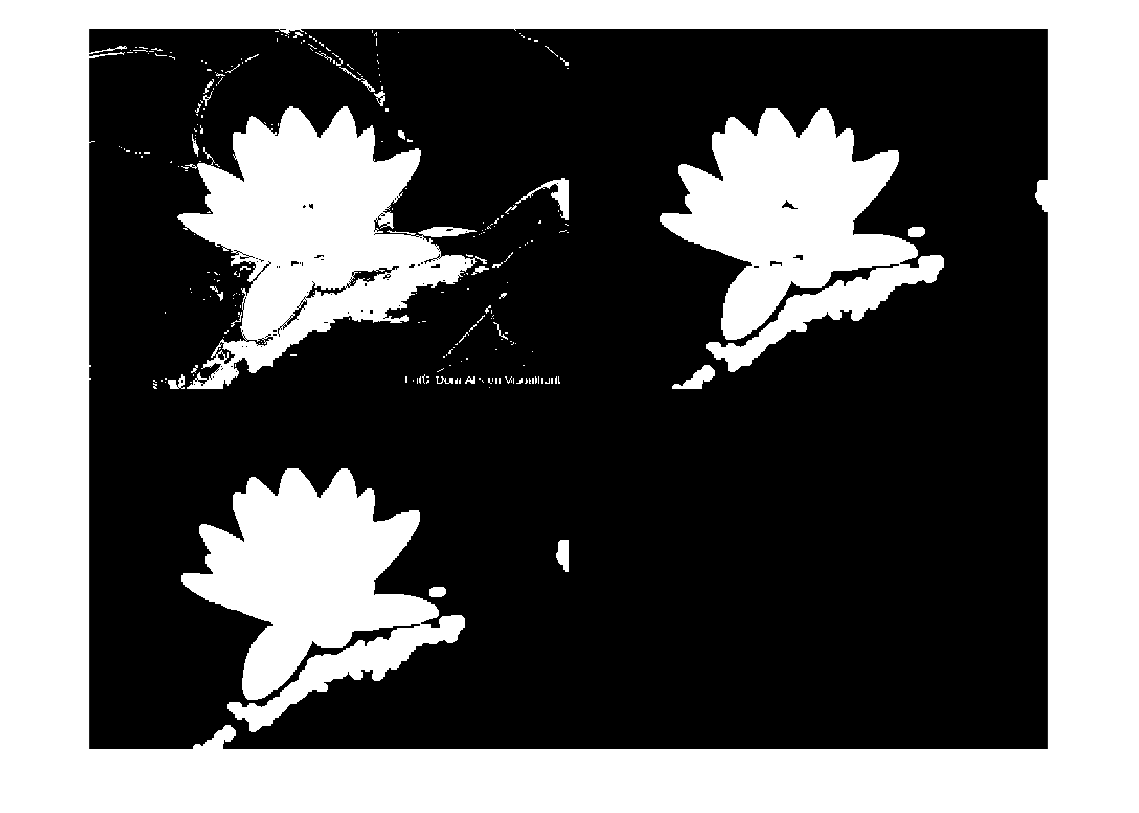

se = strel('disk', 5);  
Mopen= imopen(M, se);
MfillHoles = imfill(Mopen, 'holes');
montage({M,Mopen,MfillHoles});

image = MfillHoles;

## B. Informació kmeans

**Traieu o afegiu altres fons d’informació del píxel a les observacions del kmeans (columnes de la taula O). Observeu el resultat obtinguts amb diferents imatges.	**

Podem afegir al kmeans la distància al centre de la imatge, doncs suposem que l'usuari "centra" mitjanament l'objecte a segmentar. 

El codi rellevant per afegir aquesta informació es:

%Punt mitjà:
yMed = round ((y1+y2)/2);
xMed = round ((x1+x2)/2);

%Matriu al punt mitj:
imMedy = arrayfun(@(pixel)(pixel(1)-yMed), I);
imMedx = arrayfun(@(pixel)(pixel(1)-xMed), I);

imHxHySV(:,:,5) = imMedy(:,:,1);
imHxHySV(:,:,6) = imMedx(:,:,1);

## 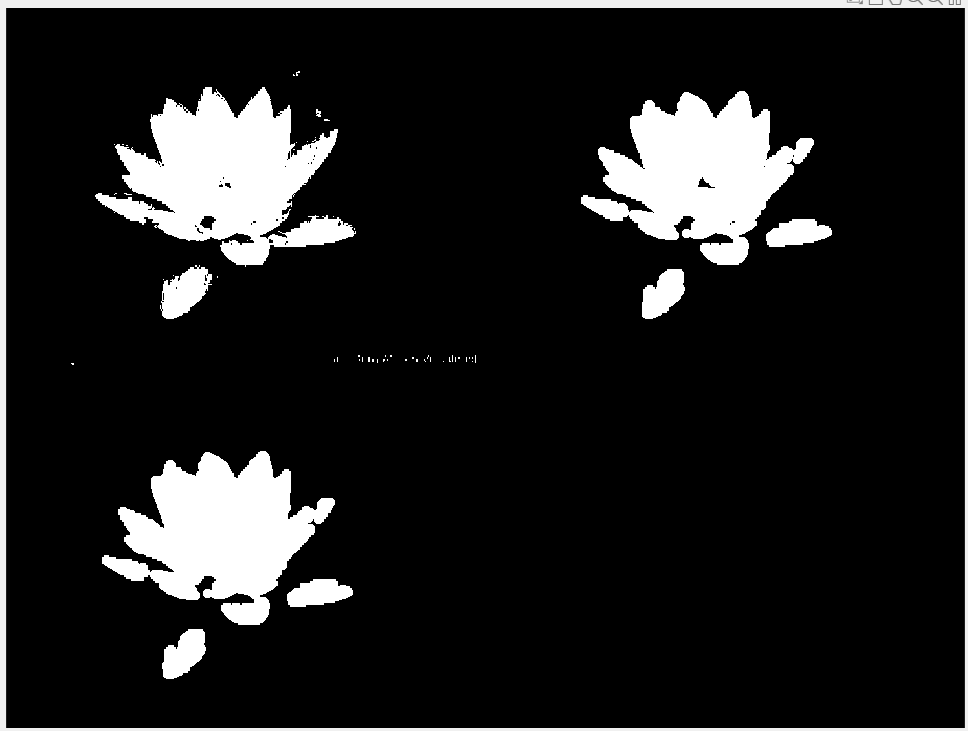

Adjunto el codi sencer en un arxiu adjut (codeB.m).

## C. Iteracions

**Es pot tornar aplicar el mateix procediment però ara amb els nous resultats de la primera iteració per millorar el resultat final? 			**

Podriem generar un codi on iterem amb aquest mateix codi per millorar la segmentació. 

La condicion de final la podriem obtenir fent la resta de la nova imatge resultant amb la anterior i comparant amb un factor de precisió predefinit. 